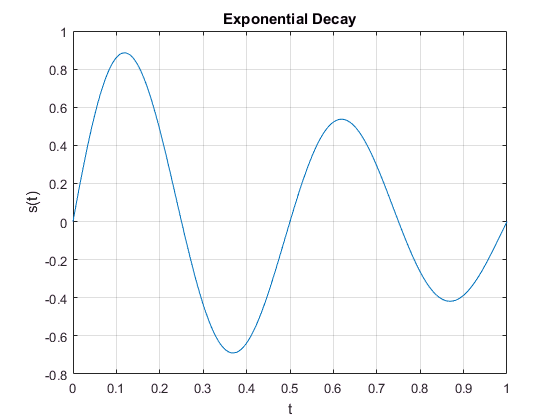

% Assignment 4
% Juan Silva
% ECE 309
% Feb. 20, 2018

clear, clc, close all
format short, format compact

% /// PROBLEM SET 7 ///

% 1.  Generate a plot for the decaying exponential:
% s(t) = sin(4pt) exp(-t),   for t values from 0 to 1 sec.

t = 0:0.001:1;               
s = sin(4*pi*t) .* exp(-t);    

plot(t,s), xlabel('t'),ylabel('s(t)')
grid, title('Exponential Decay')

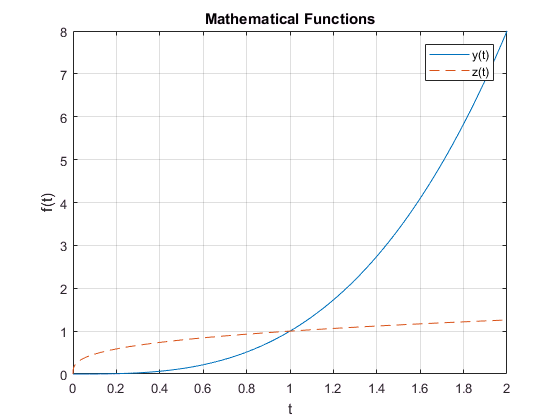


% 2. Plot y(t) = t^3 and z(t) = t^1/3, for 0 <= t <= 2,  on a 
% single graph. Make the plot for zadashed line, and 
% the plot for ya solid line.

t = 0:0.001:2;
y = t.^3;
z = t.^(1/3);

plot(t,y,t,z,'--') 
xlabel('t'), ylabel('f(t)');
grid, title('Mathematical Functions');
legend('y(t)', 'z(t)')

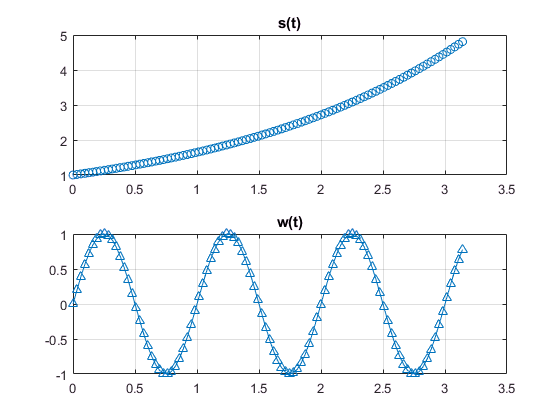


% 3.  Plot s(t) = et/2, and w(t) = sin(2pt), for 0 <= t <= p, one 
%     underneath the other on a single page. Use circles for 
%     the data points for s, with no line connecting the points.
%     Use triangles for the data points for w, with a solid line 
%     connecting the points.

t = linspace(0, pi, 100);
s = exp(t/2);
w = sin(2*pi*t);

subplot(2,1,1), plot(t,s,'o')
grid, title('s(t)');
subplot(2,1,2), plot(t,w,'-^')
grid, title('w(t)'); figure

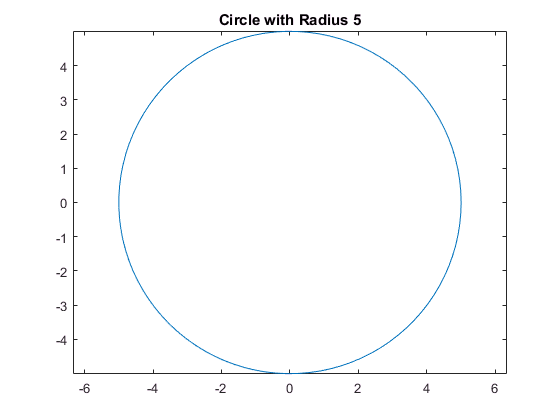




% % 4. Recall that the x and y coordinates for a point on a circle of 
% radius r, at angle q, are:    x = r cos(q),y = r sin(q).  To plot a 
% circle of radius 5:

% a. Create a vector containing 100  q-values, linearly spaced
% between 0 and 2pi.
v = linspace(0, 2*pi,100);

% b. Create a vector of corresponding x values (one for each value of q) 
% and another vector of corresponding y values (one for each value of q), 
% assuming that the radius of the circle is 5.
x = 5 * cos(v);
y = 5 * sin(v);

% d. Generate a plot of (x, y) values. After your plot command, insert the 
% command:   axis(‘equal’)   to make the scaling on the x and y axes identical 
% (to avoid distortion of the circle).
plot(x,y)
title('Circle with Radius 5')
axis('equal')

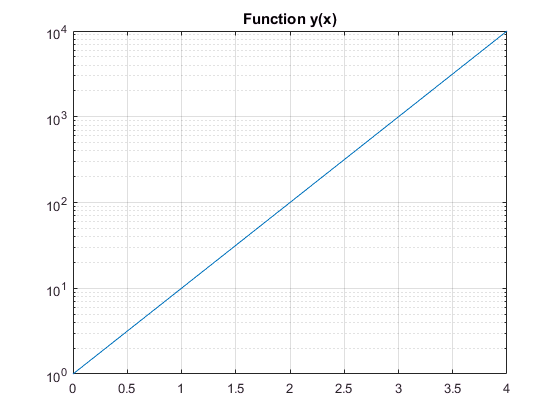

figure

% 5. Plot the function y = 10x, for x values ranging from  0 to 4, using a 
%     linear scale on the x-axis and a log scale on the y-axis.
x = linspace(0,4,100);
y = 10.^x;
semilogy(x,y), grid
title('Function y(x)')

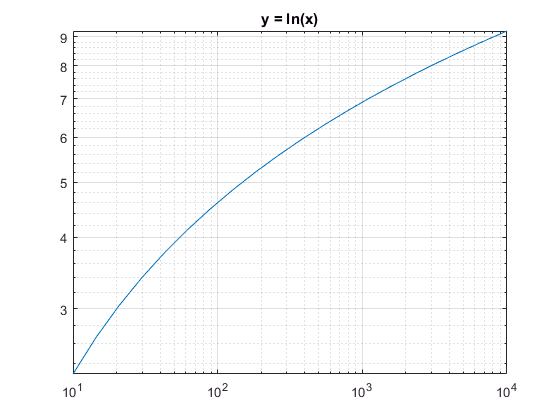


% 6. Generate a vector x containing 20 points, logarithmically spaced, between 1 
% and 10,000. Plot y = ln(x), using a log scale on both the x and y axes.
x = logspace(1,4,20);         % 1 - 10^4; 20 spaces
y = log(x);

loglog(x,y), grid
title('y = ln(x)')

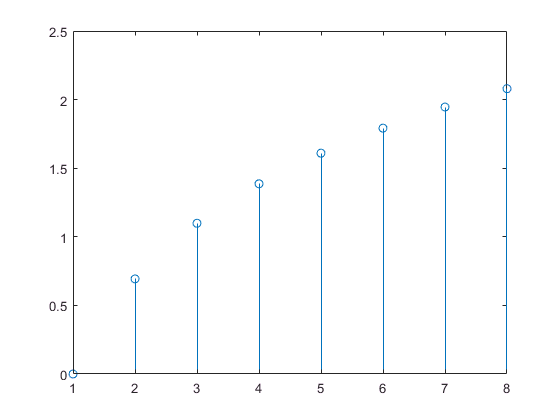

% 7a. For integer values of n ranging from 0 to 8, plot the discrete data set:   
% x[n] = ln(n)

n = [0:8];
x = log(n);
stem(n,x)

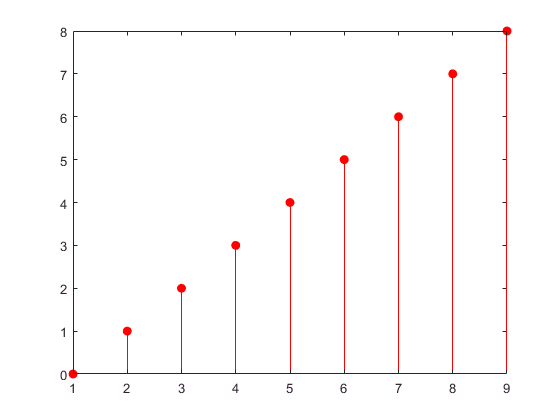


% 7b. Generate another plot for the data given in 7a, with the data circles filled in.

m = [0:8];
y = log(m);
stem(m,'ro', 'filled')

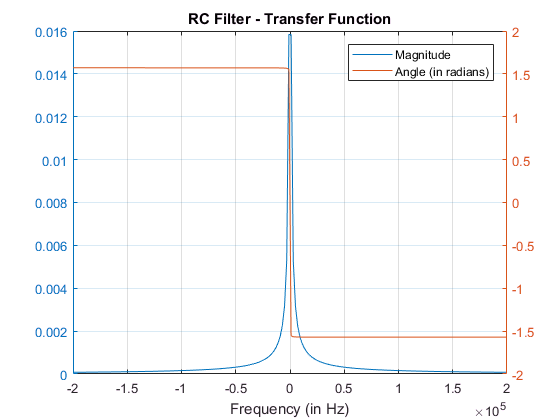


% 8. Recall that the RC filter has transfer function:  H(f) =  (1 + 2*pi*f*R*C)^-1              . 
% For frequencies ranging from f = -200 KHz to 200 KHz, with R = 10 KΩ and C = 1 µF, 
% plot the magnitude and phase angle for the transfer function, on one plot, with the 
% left vertical axis showing |H(f)|, and the right vertical axis showing the phase angle, 
% in radians.

R = 10e3;     %kΩ
C = 1e-6;     %µF

f = linspace(-200e3, 200e3, 200);
h = (1 + j*2*pi*f*R*C).^-1;

magH = abs(h);
angH = angle(h);

% Magnitude is left side
plotyy(f,magH,f,angH)
grid
title('RC Filter - Transfer Function');
legend('Magnitude', 'Angle (in radians)')
xlabel('Frequency (in Hz)')